Forward Kinematics of two link arm

theta1 = 0:1:90;
%theta2 = 0:1:360;
theta2 = zeros(91);
L1 = 4;
L2 = 5;

[X2,Y2,Xf,Yf] = fkinematics(theta1,theta2,L1,L2);

X2 =     4.0000    3.9994    3.9976    3.9945    3.9903    3.9848    3.9781    3.9702    3.9611    3.9508    3.9392    3.9265    3.9126    3.8975    3.8812    3.8637    3.8450    3.8252    3.8042    3.7821    3.7588    3.7343    3.7087    3.6820    3.6542    3.6252    3.5952    3.5640    3.5318    3.4985    3.4641    3.4287    3.3922    3.3547    3.3162    3.2766    3.2361    3.1945    3.1520    3.1086    3.0642    3.0188    2.9726    2.9254    2.8774    2.8284    2.7786    2.7280    2.6765    2.6242


Y2 =          0    0.0698    0.1396    0.2093    0.2790    0.3486    0.4181    0.4875    0.5567    0.6257    0.6946    0.7632    0.8316    0.8998    0.9677    1.0353    1.1025    1.1695    1.2361    1.3023    1.3681    1.4335    1.4984    1.5629    1.6269    1.6905    1.7535    1.8160    1.8779    1.9392    2.0000    2.0602    2.1197    2.1786    2.2368    2.2943    2.3511    2.4073    2.4626    2.5173    2.5712    2.6242    2.6765    2.7280    2.7786    2.8284    2.8774    2.9254    2.9726    3.0188


Xf =     9.0000    8.9986    8.9945    8.9877    8.9781    8.9658    8.9507    8.9329    8.9124    8.8892    8.8633    8.8346    8.8033    8.7693    8.7327    8.6933    8.6514    8.6067    8.5595    8.5097    8.4572    8.4022    8.3447    8.2845    8.2219    8.1568    8.0891    8.0191    7.9465    7.8716    7.7942    7.7145    7.6324    7.5480    7.4613    7.3724    7.2812    7.1877    7.0921    6.9943    6.8944    6.7924    6.6883    6.5822    6.4741    6.3640    6.2519    6.1380    6.0222    5.9045
    9.0000    8.9986    8.9945    8.9877    8.9781    8.9658    8.9507    8.9329    8.9124    8.8892    8.8633    8.8346    8.8033    8.7693    8.7327    8.6933    8.6514    8.6067    8.5595    8.5097    8.4572    8.4022    8.3447    8.2845    8.2219    8.1568    8.0891    8.0191    7.9465    7.8716    7.7942    7.7145    7.6324    7.5480    7.4613    7.3724    7.2812    7.1877    7.0921    6.9943    6.8944    6.7924    6.6883    6.5822    6.4741    6.3640    6.2519    6.1380    6.0222    

Yf =          0    0.1571    0.3141    0.4710    0.6278    0.7844    0.9408    1.0968    1.2526    1.4079    1.5628    1.7173    1.8712    2.0246    2.1773    2.3294    2.4807    2.6313    2.7812    2.9301    3.0782    3.2253    3.3715    3.5166    3.6606    3.8036    3.9453    4.0859    4.2252    4.3633    4.5000    4.6353    4.7693    4.9018    5.0327    5.1622    5.2901    5.4163    5.5410    5.6639    5.7851    5.9045    6.0222    6.1380    6.2519    6.3640    6.4741    6.5822    6.6883    6.7924
         0    0.1571    0.3141    0.4710    0.6278    0.7844    0.9408    1.0968    1.2526    1.4079    1.5628    1.7173    1.8712    2.0246    2.1773    2.3294    2.4807    2.6313    2.7812    2.9301    3.0782    3.2253    3.3715    3.5166    3.6606    3.8036    3.9453    4.0859    4.2252    4.3633    4.5000    4.6353    4.7693    4.9018    5.0327    5.1622    5.2901    5.4163    5.5410    5.6639    5.7851    5.9045    6.0222    6.1380    6.2519    6.3640    6.4741    6.5822    6.6883    

figure
plot_bot(X2,Y2,Xf,Yf);


Create Polygon and plot it

b_left_corner = [2,2]

b_left_corner =      2     2


width = 4

width = 4

height = 4

height = 4

p1 = b_left_corner;
p2 = b_left_corner+[width,0];
p3 = b_left_corner+[width,height];
p4 = b_left_corner+[0,height];
pgon = polyshape([p1(1),p2(1),p3(1),p4(1)],[p1(2),p2(2),p3(2),p4(2)])

pgon =   polyshape with properties:

      Vertices: [4×2 double]
    NumRegions: 1
      NumHoles: 0


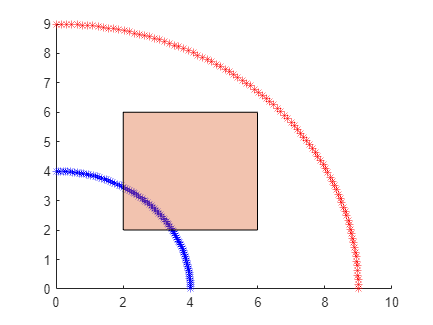

plot(pgon)

Inverse Kinematics

L3 = sqrt(Xf^2+Yf^2)

L3 =    68.4203   69.0096   69.5835   70.1422   70.6859   71.2147   71.7289   72.2285   72.7138   73.1849   73.6419   74.0849   74.5141   74.9295   75.3313   75.7195   76.0943   76.4557   76.8039   77.1388   77.4605   77.7692   78.0649   78.3476   78.6174   78.8743   79.1184   79.3498   79.5684   79.7744   79.9677   80.1484   80.3165   80.4720   80.6150   80.7455   80.8635   80.9690   81.0621   81.1428   81.2110   81.2668   81.3102   81.3411   81.3597   81.3659   81.3597   81.3411   81.3102   81.2668
   68.4203   69.0096   69.5835   70.1422   70.6859   71.2147   71.7289   72.2285   72.7138   73.1849   73.6419   74.0849   74.5141   74.9295   75.3313   75.7195   76.0943   76.4557   76.8039   77.1388   77.4605   77.7692   78.0649   78.3476   78.6174   78.8743   79.1184   79.3498   79.5684   79.7744   79.9677   80.1484   80.3165   80.4720   80.6150   80.7455   80.8635   80.9690   81.0621   81.1428   81.2110   81.2668   81.3102   81.3411   81.3597   81.3659   81.3597   81.3411   81.3102   8

theta2prime = acosd((L1^2+L2^2-L3^2)/(2*L1*L2))

theta2prime = 1.0e+02 *

   1.8000 - 5.7781i   1.8000 - 5.7830i   1.8000 - 5.7878i   1.8000 - 5.7923i   1.8000 - 5.7968i   1.8000 - 5.8010i   1.8000 - 5.8052i   1.8000 - 5.8091i   1.8000 - 5.8130i   1.8000 - 5.8167i   1.8000 - 5.8202i   1.8000 - 5.8237i   1.8000 - 5.8270i   1.8000 - 5.8302i   1.8000 - 5.8332i   1.8000 - 5.8362i   1.8000 - 5.8390i   1.8000 - 5.8417i   1.8000 - 5.8443i   1.8000 - 5.8468i   1.8000 - 5.8492i   1.8000 - 5.8515i   1.8000 - 5.8537i   1.8000 - 5.8557i   1.8000 - 5.8577i   1.8000 - 5.8596i   1.8000 - 5.8613i   1.8000 - 5.8630i   1.8000 - 5.8646i   1.8000 - 5.8661i   1.8000 - 5.8675i   1.8000 - 5.8687i   1.8000 - 5.8699i   1.8000 - 5.8711i   1.8000 - 5.8721i   1.8000 - 5.8730i   1.8000 - 5.8738i   1.8000 - 5.8746i   1.8000 - 5.8752i   1.8000 - 5.8758i   1.8000 - 5.8763i   1.8000 - 5.8767i   1.8000 - 5.8770i   1.8000 - 5.8772i   1.8000 - 5.8773i   1.8000 - 5.8774i   1.8000 - 5.8773i   1.8000 - 5.8772i   1.8000 - 5.8770i   1.8000 - 5.8767i
   1.8000 - 5.7781i   1.

theta2d = 180-theta2prime

theta2d = 1.0e+02 *

   0.0000 + 5.7781i   0.0000 + 5.7830i   0.0000 + 5.7878i   0.0000 + 5.7923i   0.0000 + 5.7968i   0.0000 + 5.8010i   0.0000 + 5.8052i   0.0000 + 5.8091i   0.0000 + 5.8130i   0.0000 + 5.8167i   0.0000 + 5.8202i   0.0000 + 5.8237i   0.0000 + 5.8270i   0.0000 + 5.8302i   0.0000 + 5.8332i   0.0000 + 5.8362i   0.0000 + 5.8390i   0.0000 + 5.8417i   0.0000 + 5.8443i   0.0000 + 5.8468i   0.0000 + 5.8492i   0.0000 + 5.8515i   0.0000 + 5.8537i   0.0000 + 5.8557i   0.0000 + 5.8577i   0.0000 + 5.8596i   0.0000 + 5.8613i   0.0000 + 5.8630i   0.0000 + 5.8646i   0.0000 + 5.8661i   0.0000 + 5.8675i   0.0000 + 5.8687i   0.0000 + 5.8699i   0.0000 + 5.8711i   0.0000 + 5.8721i   0.0000 + 5.8730i   0.0000 + 5.8738i   0.0000 + 5.8746i   0.0000 + 5.8752i   0.0000 + 5.8758i   0.0000 + 5.8763i   0.0000 + 5.8767i   0.0000 + 5.8770i   0.0000 + 5.8772i   0.0000 + 5.8773i   0.0000 + 5.8774i   0.0000 + 5.8773i   0.0000 + 5.8772i   0.0000 + 5.8770i   0.0000 + 5.8767i
   0.0000 + 5.7781i   0.0000

alpha = atan2d(Yf,Xf)

alpha =          0    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000   31.0000   32.0000   33.0000   34.0000   35.0000   36.0000   37.0000   38.0000   39.0000   40.0000   41.0000   42.0000   43.0000   44.0000   45.0000   46.0000   47.0000   48.0000   49.0000
         0    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000   31.0000   32.0000   33.0000   34.0000   35.0000   36.0000   37.0000   38.0000   39.0000   40.0000   41.0000   42.0000   43.0000   44.0000   45.0000   46.0000   47.0000   48.0000 

beta = acosd((L1^2+L3^2-L2^2)/(2*L1*L3))

beta =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN

theta1d = alpha-beta

theta1d =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   

Functions

function [x2,y2,xf,yf] = fkinematics(theta1,theta2,L1,L2)
    x2 = (cosd(theta1)*L1);
    y2 = (sind(theta1)*L1);
    xf = x2+(cosd(theta1+theta2)*L2);
    yf = y2+(sind(theta1+theta2)*L2);
end

function plot_bot(x2,y2,xf,yf)
    hold on
    %draw lines
    
    %draw dots
    plot(x2,y2, "Color", "Blue", "Marker", "*")
    plot(xf,yf, "Color", "Red", "Marker", "*")
end

function [theta1s, theta2s] = inverse_kin(Xfs,Yfs,L1,L2)
    L3 = sqrt(Xf.^2+Yf.^2)
    theta2prime = acosd((L1.^2+L2.^2-L3.^2)./(2*L1*L2))
    theta2s = 180-theta2prime
    alpha = atan2d(Yf,Xf)
    beta = acosd((L1.^2+L3.^2-L2.^2)./(2*L1*L3))
    theta1s = alpha-beta
end

function [cspace] = configuration_space(workspace,obstacles,robot)
%for each obstacle
    if isinterior(shape,xi,yi)
     [bad_t1s(i),bad_t2s(i)] = inverse_kin(xi,yi,L1,L2)
    end
end